load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
% lateralSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-disagree, 1-agree
% orderSheet= zeros(Delta_e_steps, Delta_i_steps); % -1-NaN, 0-disagree, 1-agree
% gammaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noGamma, XX-frequency
% betaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noBeta, XX-frequency
% ratioSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, X-ratio
% osciSheet = zeros(Delta_e_steps, Delta_i_steps,5,2); % -1-NaN, 0-noOsci, 1-hasOsci; before and after

agree = orderSheet == 3;
disagree = orderSheet == 1 | orderSheet == 2;
orderSheet(agree) = 1;
orderSheet(disagree) = 0;
orderSheet = flip(orderSheet');

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 100;

n = 1:100;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);

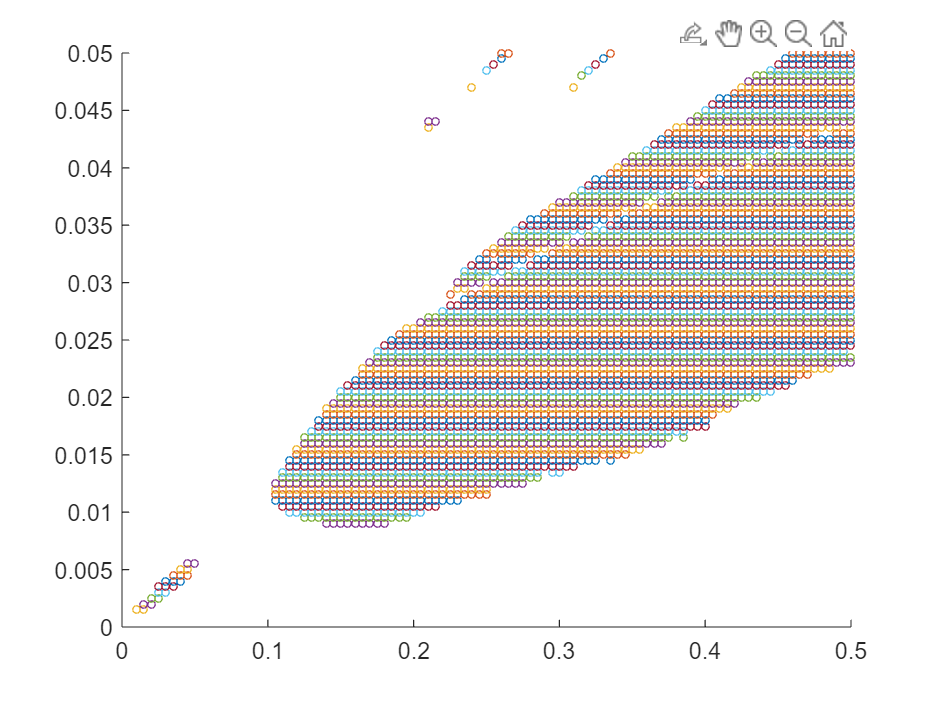

roi = orderSheet == 1;

sz = 10;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz);
    hold on
end
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);